timeDiffStd = readtable('timeDiff_Std.csv', 'HeaderLines', 1);
timeDiffAvg = readtable('timeDiff_AVG.csv', 'HeaderLines', 1);
timeDiffFTA = readtable('timeDiff_FTA.csv', 'HeaderLines', 1);

phases = [30; 60; 90; 120; 150; 180];
meansStd = [
    mean(timeDiffStd.Var2(1000:3000)); 
    mean(timeDiffStd.Var2(3001:6000)); 
    mean(timeDiffStd.Var2(6001:9000)); 
    mean(timeDiffStd.Var2(9001:12000));
    mean(timeDiffStd.Var2(12001:15000));
    mean(timeDiffStd.Var2(15001:end));
    ];
meansAVG = [
    mean(timeDiffAvg.Var2(1000:3000)); 
    mean(timeDiffAvg.Var2(3001:6000)); 
    mean(timeDiffAvg.Var2(6001:9000)); 
    mean(timeDiffAvg.Var2(9001:12000));
    mean(timeDiffAvg.Var2(12001:15000));
    mean(timeDiffAvg.Var2(15001:end));
    ];
meansFTA = [
    mean(timeDiffFTA.Var2(1:3000)); 
    mean(timeDiffFTA.Var2(3001:6000)); 
    mean(timeDiffFTA.Var2(6001:9000)); 
    mean(timeDiffFTA.Var2(9001:12000));
    mean(timeDiffFTA.Var2(12001:15000));
    mean(timeDiffFTA.Var2(15001:end));
    ];

% jittersStd = [
%     std(timeDiffStd.Var2(1000:3000)); 
%     std(timeDiffStd.Var2(3001:6000)); 
%     std(timeDiffStd.Var2(6001:9000)); 
%     std(timeDiffStd.Var2(9001:12000));
%     std(timeDiffStd.Var2(12001:15000));
%     std(timeDiffStd.Var2(15001:end));
%     ];
% jittersAVG = [
%     std(timeDiffAvg.Var2(1000:3000)); 
%     std(timeDiffAvg.Var2(3001:6000)); 
%     std(timeDiffAvg.Var2(6001:9000)); 
%     std(timeDiffAvg.Var2(9001:12000));
%     std(timeDiffAvg.Var2(12001:15000));
%     std(timeDiffAvg.Var2(15001:end));
%     ];
% jittersFTA = [
%     std(timeDiffFTA.Var2(1000:3000)); 
%     std(timeDiffFTA.Var2(3001:6000)); 
%     std(timeDiffFTA.Var2(6001:9000)); 
%     std(timeDiffFTA.Var2(9001:12000));
%     std(timeDiffFTA.Var2(12001:15000));
%     std(timeDiffFTA.Var2(15001:end));
%     ];

jittersStd = [
    [max(timeDiffStd.Var2(1:3000)), min(timeDiffStd.Var2(1:3000))]; 
    [max(timeDiffStd.Var2(3001:6000)), min(timeDiffStd.Var2(3001:6000))]; 
    [max(timeDiffStd.Var2(6001:9000)), min(timeDiffStd.Var2(6001:9000))]; 
    [max(timeDiffStd.Var2(9001:12000)), min(timeDiffStd.Var2(9001:12000))];
    [max(timeDiffStd.Var2(12001:15000)), min(timeDiffStd.Var2(12001:15000))];
    [max(timeDiffStd.Var2(15001:end)), min(timeDiffStd.Var2(15001:end))];
    ];
jittersAVG = [
    [max(timeDiffAvg.Var2(1:3000)), min(timeDiffAvg.Var2(1:3000))]; 
    [max(timeDiffAvg.Var2(3001:6000)), min(timeDiffAvg.Var2(3001:6000))]; 
    [max(timeDiffAvg.Var2(6001:9000)), min(timeDiffAvg.Var2(6001:9000))]; 
    [max(timeDiffAvg.Var2(9001:12000)), min(timeDiffAvg.Var2(9001:12000))];
    [max(timeDiffAvg.Var2(12001:15000)), min(timeDiffAvg.Var2(12001:15000))];
    [max(timeDiffAvg.Var2(15001:end)), min(timeDiffAvg.Var2(15001:end))];
    ];
jittersFTA = [
    [max(timeDiffFTA.Var2(1:3000)), min(timeDiffFTA.Var2(1:3000))]; 
    [max(timeDiffFTA.Var2(3001:6000)), min(timeDiffFTA.Var2(3001:6000))]; 
    [max(timeDiffFTA.Var2(6001:9000)), min(timeDiffFTA.Var2(6001:9000))]; 
    [max(timeDiffFTA.Var2(9001:12000)), min(timeDiffFTA.Var2(9001:12000))];
    [max(timeDiffFTA.Var2(12001:15000)), min(timeDiffFTA.Var2(12001:15000))];
    [max(timeDiffFTA.Var2(15001:end)), min(timeDiffFTA.Var2(15001:end))];
    ];

avgPhases = table(phases, meansStd, jittersStd, meansAVG, jittersAVG, meansFTA, jittersFTA);

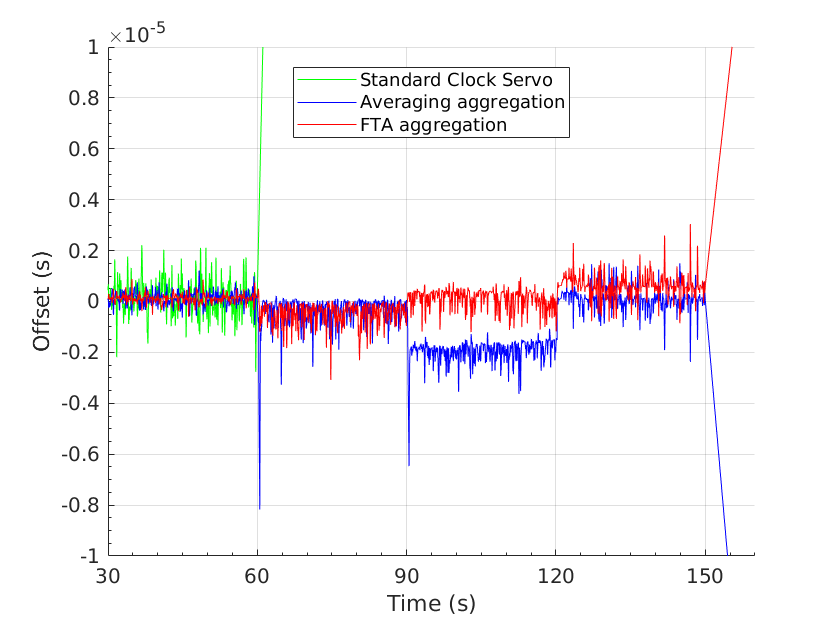

f1 = figure;
hold on;

plot(timeDiffStd.Var1, timeDiffStd.Var2, "-", 'Color' ,'g');
plot(timeDiffAvg.Var1, timeDiffAvg.Var2, "-", 'Color' ,'b');
plot(timeDiffFTA.Var1, timeDiffFTA.Var2, "-", 'Color' ,'r');

legend("Standard Clock Servo", "Averaging aggregation", "FTA aggregation",'Location', 'North');
xlabel("Time (s)");
ylabel("Offset (s)");
set(gca,'XMinorTick','on','YMinorTick','on');
ylim([-10e-6 10e-6]);
xlim([30, 160]);
xticks(phases);
grid on;
hold off;

saveas(f1, "timeDiffTrace", 'svg');

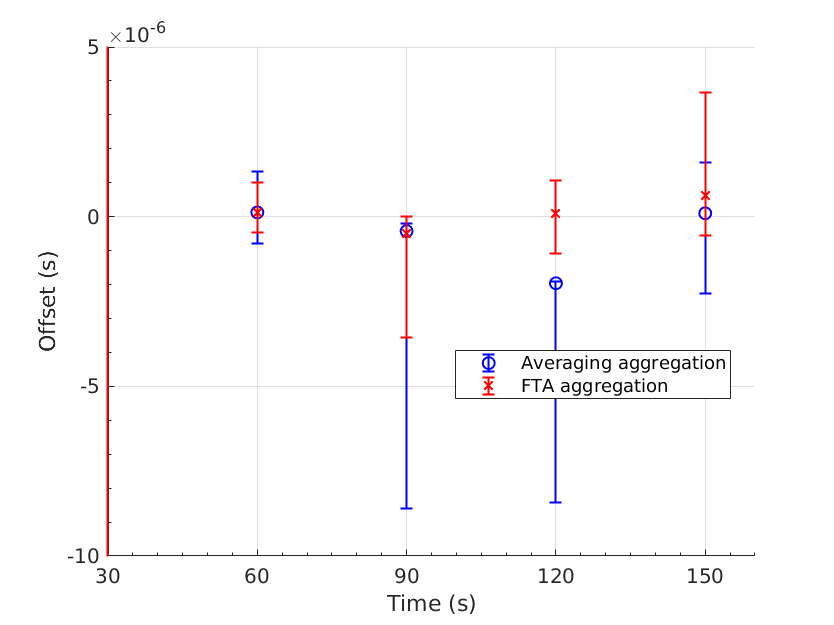

f2 = figure;
hold on;

errorbar(avgPhases.phases, avgPhases.meansAVG, avgPhases.jittersAVG(:,2), avgPhases.jittersAVG(:,1), "o", 'Color', 'b','LineWidth',1);
errorbar(avgPhases.phases, avgPhases.meansFTA, avgPhases.jittersFTA(:,2), avgPhases.jittersFTA(:,1), "x", 'Color', 'r','LineWidth',1);

legend("Averaging aggregation", "FTA aggregation",'Location', 'Best');
xlabel("Time (s)");
ylabel("Offset (s)");
set(gca,'XMinorTick','on','YMinorTick','on');
ylim([-10e-6 5e-6]);
xlim([30, 160]);
xticks(phases);
grid on;
hold off;

saveas(f2, 'timeDiffMeanJitters','svg');